`Q-2(a) - MLE`

% Clear workspace and command window
clear;
clc;

% Initialize parameters
R = 400;
alpha_mle = zeros(1, R);
beta_mle = zeros(1, R);
sigma_mle = zeros(1, R);
sd_true = zeros(1, R);
alpha_true = 900;
beta_true = 1.2;
N = 500;

% Loop over R iterations
for r = 1:R
    % Generate random data
    X = normrnd(0.2, sqrt(0.5), [1, N]);
    signal = alpha_true * (exp(-beta_true * X));
    sigvar = var(signal);
    SNR = 10;
    noise_var = sigvar / 10;
    sd = sqrt(noise_var);
    sd_true(r) = sd;

    % Add noise to the signal
    v = normrnd(0, sqrt(noise_var), [1, N]);
    y = signal + v;

    % Define the negative log-likelihood function
    neg_loglikelihood = @(params) (N/2)*log(2*pi*(params(3)^2)) + (1/(2*params(3)^2))*sum((y - params(1)*exp(-params(2)*X)).^2);

    % Initial guess for parameters (alpha, beta)
    initial_guess = [890, 0.8, sd];  

    % Minimize the negative log-likelihood function using fminunc
    [estimated_params, negative_log_likelihood] = fminunc(neg_loglikelihood, initial_guess);

    % Extract estimated parameters
    estimated_alpha = estimated_params(1);
    estimated_beta = estimated_params(2);
    estimated_sigma = estimated_params(3);
    alpha_mle(r) = estimated_alpha;
    beta_mle(r) = estimated_beta;
    sigma_mle(r) = estimated_sigma;
end


% Calculate variances
variance_alpha_mle = var(alpha_mle);
variance_beta_mle = var(beta_mle);
variance_sigma_mle = var(sigma_mle);

% Display estimated parameters
disp(['Estimated alpha for part A: ', num2str(mean(alpha_mle))]);

Estimated alpha for part A: 899.1023


disp(['Estimated beta for part A: ', num2str(mean(beta_mle))]);

Estimated beta for part A: 1.2006


disp(['Estimated sigma for part A: ', num2str(mean(sigma_mle))]);

Estimated sigma for part A: 328.5731



% Calculate biases
beta_bias_mle = mean(beta_mle) - beta_true;
alpha_bias_mle = mean(alpha_mle) - alpha_true;
sigma_bias_mle = mean(mean(sigma_mle)) - mean(sd_true);

`Q-2(b) - Modified OLS`

% Initialize parameters
alpha_ols = zeros(1, R);
beta_ols = zeros(1, R);
sigma_ols = zeros(1, R);
sd_true = zeros(1, R);
alpha_true = 900;
beta_true = 1.2;
N = 500;

% Loop over R iterations
for r = 1:R
    % Generate random data
    X = normrnd(0.2, sqrt(0.5), [1, N]);
    signal = alpha_true * (exp(-beta_true * X));
    sigvar = var(signal);
    SNR = 10;
    noise_var = sigvar / 10;
    sd = sqrt(noise_var);
    sd_true(r) = sd;

    % Add noise to the signal
    v = normrnd(0, sqrt(noise_var), [1, N]);
    y = signal + v;

    % Define the objective function for OLS estimation
    obj_function = @(params) sum((log(abs(y)) - (log(params(1)) - params(2)*X)).^2);
    initial_guess = [900, 1];
    estimated_params = fminunc(obj_function, initial_guess);

    % Calculate residuals and estimate sigma
    residual = y - (estimated_params(1) * exp(-estimated_params(2) * X));
    sigma_estimated = sqrt(var(residual));

    % Extract estimated parameters
    estimated_alpha = estimated_params(1);
    estimated_beta = estimated_params(2);

    alpha_ols(r) = estimated_alpha;
    beta_ols(r) = estimated_beta;
    sigma_ols(r) = sigma_estimated;
end

% Display estimated parameters
disp(['Estimated alpha for part B: ', num2str(mean(beta_ols))]);

Estimated alpha for part B: 1.1757


disp(['Estimated beta for part B: ', num2str(mean(alpha_ols))]);

Estimated beta for part B: 826.0208


disp(['Estimated sigma for part B: ', num2str(mean(sigma_ols))]);

Estimated sigma for part B: 361.3472



% Calculate variances
variance_alpha_ols = var(alpha_ols);
variance_beta_ols = var(beta_ols);
variance_sigma_ols = var(sigma_ols);
% Calculate biases
beta_bias_ols = mean(beta_ols) - beta_true;
alpha_bias_ols = mean(alpha_ols) - alpha_true;
sigma_bias_ols = mean(mean(sigma_ols)) - mean(sd_true);

`Q-2(c) - Nonlinear Least Squares (NLS) Estimation`

alpha_nls = zeros(1, R);
beta_nls = zeros(1, R);
sigma_nls = zeros(1, R);

for r = 1:R
    % Generate random data and add noise
    X = normrnd(0.2, sqrt(0.5), [1, N]);
    signal = alpha_true * (exp(-beta_true * X));
    noise_var = var(signal) / 10;
    sd_true(r) = sqrt(noise_var);
    y = signal + normrnd(0, sqrt(noise_var), [1, N]);

    % Define the objective function for NLS estimation
    obj_function = @(params) sum((y - params(1) * exp(-params(2) * X)).^2);

    % Perform NLS estimation
    initial_guess = [900, 1];
    estimated_params = fminunc(obj_function, initial_guess);

    % Calculate residuals and estimate sigma
    residual = y - (estimated_params(1) * exp(-estimated_params(2) * X));
    sigma_estimated = sqrt(var(residual));

    % Extract estimated parameters
    alpha_nls(r) = estimated_params(1);
    beta_nls(r) = estimated_params(2);
    sigma_nls(r) = sigma_estimated;
end

% Display estimated parameters
disp(['Estimated alpha for part C: ', num2str(mean(beta_nls))]);

Estimated alpha for part C: 1.1996


disp(['Estimated beta for part C: ', num2str(mean(alpha_nls))]);

Estimated beta for part C: 900.7096


disp(['Estimated sigma for part C: ', num2str(mean(sigma_nls))]);

Estimated sigma for part C: 323.7608



% Calculate variances and biases
variance_alpha_nls = var(alpha_nls);
variance_beta_nls = var(beta_nls);
variance_sigma_nls = var(sigma_nls);
beta_bias_nls = mean(beta_nls) - beta_true;
alpha_bias_nls = mean(alpha_nls) - alpha_true;
sigma_bias_nls = mean(mean(sigma_nls)) - mean(sd_true);


`Q-2(d) - Comparison of Estimators`

% Calculate minimum variance of alpha and beta
min_variance_alpha = min([variance_alpha_mle, variance_alpha_ols, variance_alpha_nls]);
min_variance_beta = min([variance_beta_mle, variance_beta_ols, variance_beta_nls]);

% Create table
estimators = {'MLE', 'OLS', 'NLS'};
parameters = {'Alpha', 'Beta'};
bias_values = [alpha_bias_mle, beta_bias_mle;
               alpha_bias_ols, beta_bias_ols;
               alpha_bias_nls, beta_bias_nls];
variance_values = [min_variance_alpha/variance_alpha_mle, min_variance_beta/variance_beta_mle;
                   min_variance_alpha/variance_alpha_ols, min_variance_beta/variance_beta_ols;
                   min_variance_alpha/variance_alpha_nls, min_variance_beta/variance_beta_nls];

% Print table
for i = 1:numel(estimators)
    for j = 1:numel(parameters)
        fprintf('%s %s Bias: %.4f Efficiency: %.4f\n', estimators{i}, parameters{j}, bias_values(i, j), variance_values(i, j));
    end
end

MLE Alpha Bias: -0.8977 Efficiency: 0.8533
MLE Beta Bias: 0.0006 Efficiency: 0.9305
OLS Alpha Bias: -73.9792 Efficiency: 0.4287
OLS Beta Bias: -0.0243 Efficiency: 0.0598
NLS Alpha Bias: 0.7096 Efficiency: 1.0000
NLS Beta Bias: -0.0004 Efficiency: 1.0000



% Conclusion
disp('NLS is the most efficient estimator. MLE and NLS have lower bias than OLS. OLS may not be suitable for this problem.');

NLS is the most efficient estimator. MLE and NLS have lower bias than OLS. OLS may not be suitable for this problem.


`Q - 3 (a) - OLS`

Phi=normalize(Phi);
y=normalize(y);
mdl1=fitlm(Phi,y)

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    _________    __________    __________

    (Intercept)    9.0044e-16    0.0083056    1.0841e-13             1
    x1                0.55843      0.14302        3.9045    0.00044089
    x2               -0.05628     0.071289      -0.78946       0.43548
    x3                0.21306      0.10904        1.9539      0.059231
    x4                0.17878      0.12475        1.4331       0.16125
    x5                 0.1122     0.047886        2.3432      0.025298
    x6                -0.1584     0.024491       -6.4679    2.4504e-07


Number

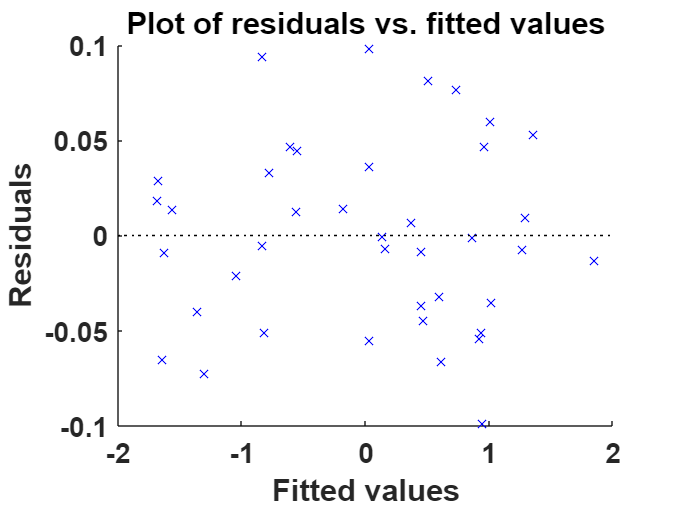

figure
plotResiduals(mdl1,"fitted")
set(gca,'fontsize',14,'fontweight','bold')
box off

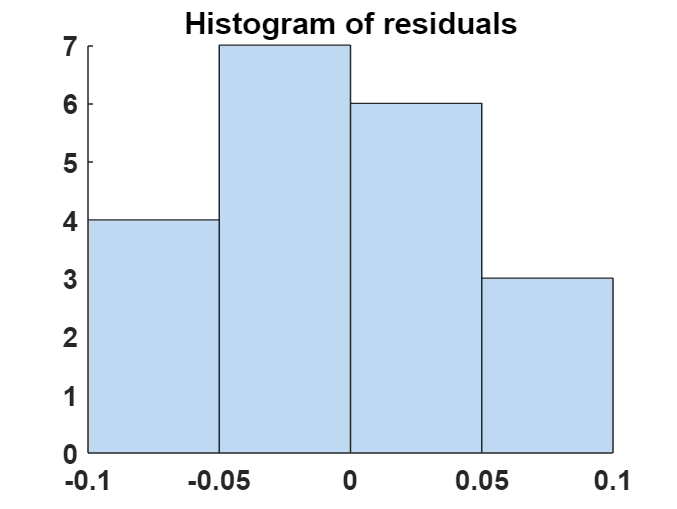

plotResiduals(mdl1,'histogram')
set(gca,'fontsize',14,'fontweight','bold')
box off

The residuals appear to closely follow a Gaussian distribution, indicating that the residuals are white noise. This validates the first assumption of considering the equation error to be sampled from a GWN.

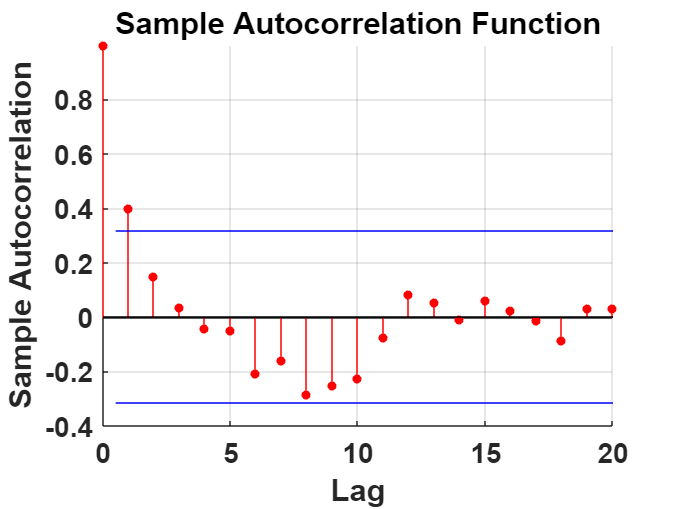

autocorr(mdl1.Residuals.Raw,20)
set(gca,'fontsize',14,'fontweight','bold')
box off

`Q-3(b) - LASSO`

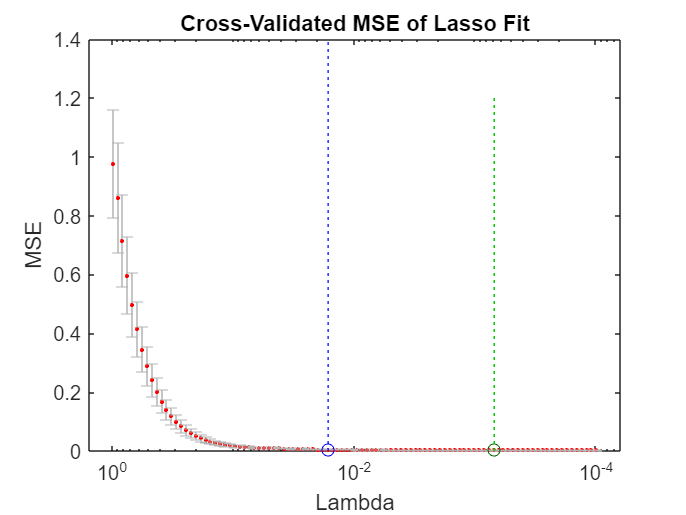

[theta_lasso, FitInfo]= lasso(Phi,y,'CV',5); 
lassoPlot(theta_lasso , FitInfo ,'PlotType','CV')

lambda_opt = FitInfo . LambdaMinMSE 

lambda_opt = 6.9320e-04

thetahat_l = theta_lasso (: , FitInfo . IndexMinMSE )

thetahat_l =     0.5749
         0
    0.1442
    0.1691
    0.1160
   -0.1452


theta=mdl1.Coefficients.Estimate

theta =     0.0000
    0.5584
   -0.0563
    0.2131
    0.1788
    0.1122
   -0.1584



y_pred = Phi * thetahat_l;
% Step 5: Compute residuals and then MSE
residuals = y - y_pred;
MSE_LASSO = mean(residuals.^2);
RMSE_LASSO=sqrt(MSE_LASSO)

RMSE_LASSO = 0.0483

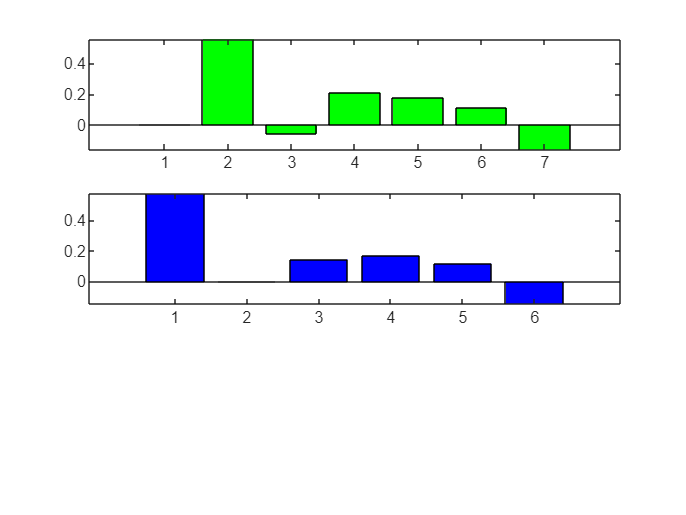

figure
subplot (3 ,1 ,1)
bar ( theta ,'g')
subplot (3 ,1 ,2)
bar ( thetahat_l ,'b')

It can be seen that LASSO forces the value of estimate for index 2 to be 0. This helps in reducing the weight of correlated estimators.

`Q-3(c) - Polynomial Regression`

`OLS`

Phi_polynomial=[Phi,Phi.^2];
mdlPolynomial1=fitlm(Phi_polynomial,y)

mdlPolynomial1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                    Estimate        SE        tStat        pValue  
                   __________    ________    ________    __________

    (Intercept)    -0.0056337    0.029139    -0.19334       0.84814
    x1                0.30735     0.28767      1.0684       0.29481
    x2                0.25633     0.18312      1.3998       0.17296
    x3                0.14222     0.11086      1.2829       0.21044
    x4                0.22936     0.18601       1.233       0.22819
    x5               0.068624    0.063391      1.0826       0.28858
    x6               -0.13721    0.034624     -3.9629    0.0

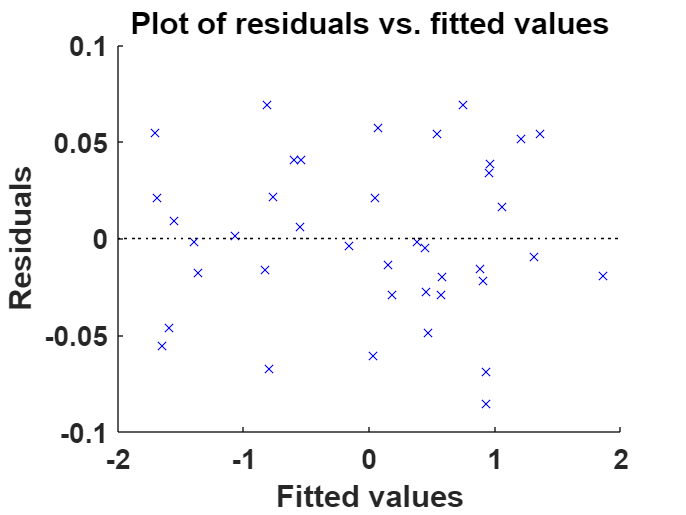

figure
plotResiduals(mdlPolynomial1,"fitted")
set(gca,'fontsize',14,'fontweight','bold')
box off

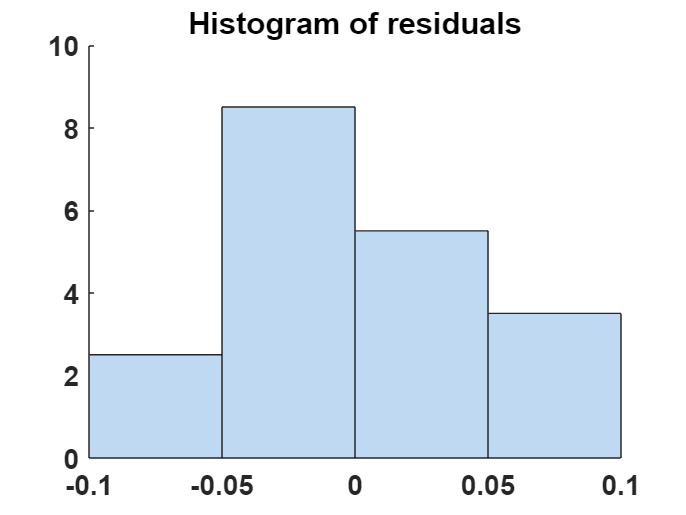

plotResiduals(mdlPolynomial1,'histogram')
set(gca,'fontsize',14,'fontweight','bold')
box off

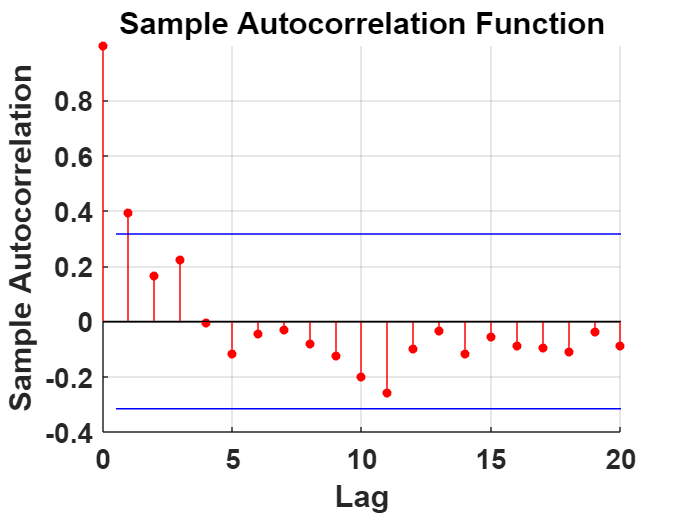

autocorr(mdlPolynomial1.Residuals.Raw,20)
set(gca,'fontsize',14,'fontweight','bold')
box off

`LASSO`

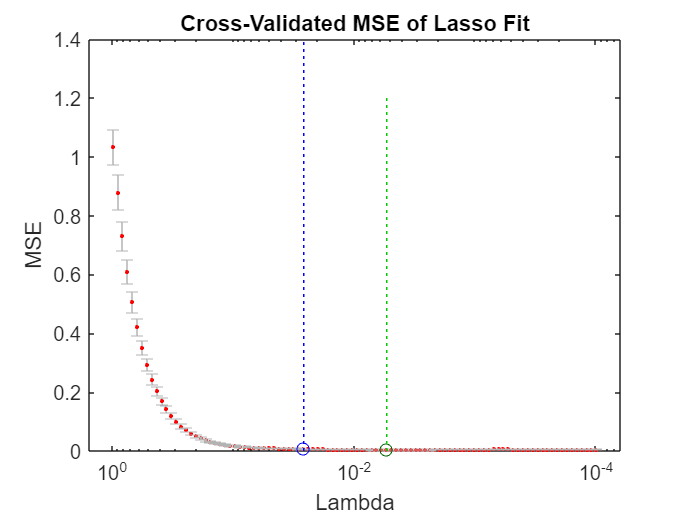

[theta_lasso_polynomial, FitInfo]= lasso(Phi_polynomial,y,'CV',5); 
lassoPlot(theta_lasso_polynomial , FitInfo ,'PlotType','CV')

lambda_opt = FitInfo . LambdaMinMSE 

lambda_opt = 0.0054

thetahat_polynomial_l = theta_lasso_polynomial (: , FitInfo . IndexMinMSE );
theta_polynomial=mdlPolynomial1.Coefficients.Estimate;

y_pred_polynomial = Phi_polynomial * thetahat_polynomial_l;
% Step 5: Compute residuals and then MSE_
residuals_polynomial = y - y_pred_polynomial;
MSE_LASSO_polynomial = mean(residuals_polynomial.^2);
RMSE_LASSO_polynomial=sqrt(MSE_LASSO_polynomial)

RMSE_LASSO_polynomial = 0.0507

% Compare model performance
MSE_ls=mdl1.MSE;
MSE_ls_polynomial=mdlPolynomial1.MSE;
disp('Linear Model Performance:');

Linear Model Performance:


disp(['MSE (LS): ', num2str(MSE_ls)]);

MSE (LS): 0.0027593


disp(['MSE (LASSO): ', num2str(MSE_LASSO)]);

MSE (LASSO): 0.0023281


disp(['RMSE (LASSO): ', num2str(RMSE_LASSO)]);

RMSE (LASSO): 0.04825



disp('Quadratic Model Performance:');

Quadratic Model Performance:


disp(['MSE (LS): ', num2str(MSE_ls_polynomial)]);

MSE (LS): 0.0024012


disp(['MSE (LASSO): ', num2str(MSE_LASSO_polynomial)]);

MSE (LASSO): 0.0025659


disp(['RMSE (LASSO): ', num2str(RMSE_LASSO_polynomial)]);

RMSE (LASSO): 0.050655



% Compare coefficient estimates
disp('Linear Model Coefficients:');

Linear Model Coefficients:


disp(theta);

    0.0000
    0.5584
   -0.0563
    0.2131
    0.1788
    0.1122
   -0.1584



disp('LASSO Linear Model Coefficients:');

LASSO Linear Model Coefficients:


disp(thetahat_l);

    0.5749
         0
    0.1442
    0.1691
    0.1160
   -0.1452




disp('Quadratic Model Coefficients:');

Quadratic Model Coefficients:


disp(theta_polynomial);

   -0.0056
    0.3073
    0.2563
    0.1422
    0.2294
    0.0686
   -0.1372
    0.1557
    0.1057
   -0.0546
   -0.1697
   -0.0469
    0.0156



disp('LASSO Quadratic Model Coefficients:');

LASSO Quadratic Model Coefficients:


disp(thetahat_polynomial_l);

    0.6769
    0.0054
    0.0003
    0.1742
    0.1345
   -0.1067
         0
         0
         0
   -0.0001
   -0.0186
    0.0012




% Compare model sparsity
disp('Sparsity (Linear Model):');

Sparsity (Linear Model):


disp(sum(thetahat_l == 0) / numel(thetahat_l));

    0.1667



disp('Sparsity (Quadratic Model):');

Sparsity (Quadratic Model):


disp(sum(thetahat_polynomial_l == 0) / numel(thetahat_polynomial_l));

    0.2500



Plotting the estimator values

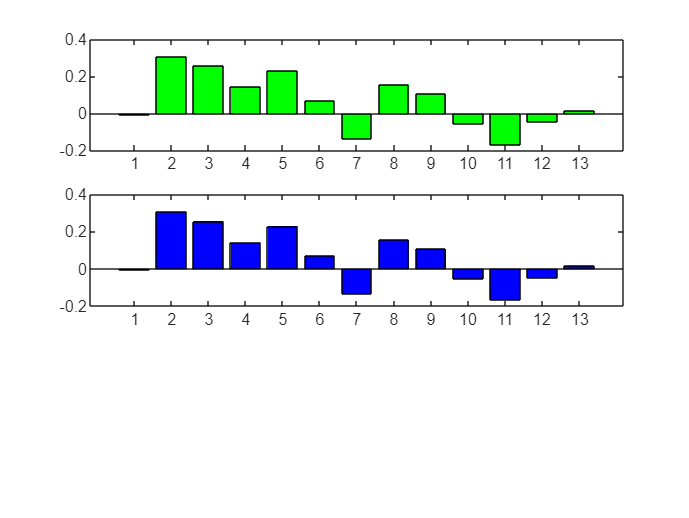

figure
subplot (3 ,1 ,1)
bar ( theta_polynomial ,'g')
subplot (3 ,1 ,2)
bar ( theta_polynomial ,'b')

`Q - 4(b)`

H = [802, -400; -400, 200];
if eig(H) > 0
    disp("Hessian Matrix is Positive Definite")
else
    disp("Hessian Matrix is not Positive Definite")
end

Hessian Matrix is Positive Definite


` Q - 5`

% Define the function
fx = @(x1,x2) 100*(x2-x1^2)^2+(1-x1)^2

fx = function_handle with value:
    @(x1,x2)100*(x2-x1^2)^2+(1-x1)^2


syms x1_sym x2_sym;

% Compute the gradient
grad_f = @(x1, x2) [2 * (200 * x1^3 - 200 * x1 * x2 + x1 - 1); 200 * (x2 - x1^2)]

grad_f = function_handle with value:
    @(x1,x2)[2*(200*x1^3-200*x1*x2+x1-1);200*(x2-x1^2)]



% Initial points
xo = [1.2 1.2]';
xo2 = [-1.2 1]';
grad_f(xo(1),xo(2));

% Set parameters
max_iter = 1500;
tol = 1e-5;
beta=0.5;
etao=1;
eta_range = linspace(0, 0.01, 1000);


`Backtracking Line Search`

x=xo

x =     1.2000
    1.2000


for iter = 1:max_iter
    grad = grad_f(x(1), x(2));  
    eta = etao;
    while fx(x(1) - eta * grad(1), x(2) - eta * grad(2)) - fx(x(1), x(2)) > 0
        eta = beta * eta;
    end
    x_new = x - eta * grad;
    if norm(x_new - x, 2) < tol
        break;
    end
    x = x_new;
end

% Display results
disp('Optimal solution using Backtracking:')

Optimal solution using Backtracking:


disp(x)

    1.0080
    1.0162



disp(['Optimal value of f(x1, x2) using Backtracking: ', num2str( fx(x(1),x(2)) )])

Optimal value of f(x1, x2) using Backtracking: 6.4767e-05


`Steepest` `Gradient` `Descent`

x=xo;
for iter = 1:max_iter
    grad = grad_f(x(1), x(2));  

    fx_eta = zeros(size(eta_range));
    for i = 1:length(eta_range)
        fx_eta(i) = fx(x(1) - eta_range(i) * grad(1), x(2) - eta_range(i) * grad(2));
    end
   
    [~, min_idx] = min(fx_eta);
    eta = eta_range(min_idx);

    x_new = x - eta * grad;
    if norm(x_new - x, 2) < tol
        break;
    end
    x = x_new;
end

% Display results
disp('Optimal solution using Steepest gradient descent:')

Optimal solution using Steepest gradient descent:


disp(x)

    1.0074
    1.0149



disp(['Optimal value of f(x1, x2) using Steepest gradient descent: ', num2str(fx(x(1), x(2)))])

Optimal value of f(x1, x2) using Steepest gradient descent: 5.5238e-05


% For the Next Point
x=xo2;
for iter = 1:max_iter
    grad = grad_f(x(1), x(2));  
    eta = etao;
    while fx(x(1) - eta * grad(1), x(2) - eta * grad(2)) -fx(x(1), x(2)) > 0
        eta = beta * eta;
    end
    x_new = x - eta * grad;
    if norm(x_new - x, 2) < tol
        break;
    end
    x = x_new;
end

% Display results
disp('Optimal solution using Backtracking:')

Optimal solution using Backtracking:


disp(x)

    0.9825
    0.9653



disp(['Optimal value of f(x1, x2) using Backtracking: ', num2str( fx(x(1),x(2)) )])

Optimal value of f(x1, x2) using Backtracking: 0.00030629


`Steepest Gradient Descent`

x=xo2;
for iter = 1:max_iter
    grad = grad_f(x(1), x(2));  

    fx_eta = zeros(size(eta_range));
    for i = 1:length(eta_range)
        fx_eta(i) = fx(x(1) - eta_range(i) * grad(1), x(2) - eta_range(i) * grad(2));
    end
   
    [~, min_idx] = min(fx_eta);
    eta = eta_range(min_idx);

    x_new = x - eta * grad;
    if norm(x_new - x, 2) < tol
        break;
    end
    x = x_new;
end
% Display results
disp('Optimal solution using Steepest gradient descent:')

Optimal solution using Steepest gradient descent:


disp(x)

    0.9762
    0.9528



disp(['Optimal value of f(x1, x2) using Steepest gradient descent: ', num2str(fx(x(1), x(2)))])

Optimal value of f(x1, x2) using Steepest gradient descent: 0.00057005


It can be observed that the computation is more complex in the case of steepest gradient descent. However, the value of the objective function is lower in the case of Steepest Gradient Descent for the same number of iterations. In the case of steepest gradient descent, a search is performed at every step to find the step size that leads to the best local minimizer. This increases the complexity.